# Cleaning Workspace

clear;
close all;
clc;

# Plot Parameters

linewidth  = 2;
markersize = 10;
fontsize   = 20;
fontname   = 'Times New Roman';

bas_size = 0.8;

legend_algo_1 = {'NS','RS','SOS','CBS','ICIBS'};
legend_algo_2 = {'RS','SOS','CBS','ICIBS'};
legend_link = {'Uplink','Downlink'};


cat_1 = categorical(legend_algo_1);
cat_1 = reordercats(cat_1,legend_algo_1);

cat_2 = categorical(legend_algo_2);
cat_2 = reordercats(cat_2,legend_algo_2);

color = [0.0000 0.4470 0.7410;
         0.8500 0.3250 0.0980;
         0.9290 0.6940 0.1250;
         0.4940 0.1840 0.5560;
         0.4660 0.6740 0.1880;
         0.3010 0.7450 0.9330;
         0.6350 0.0780 0.1840;
         0.5423 0.8950 0.0042;
         0.0430 0.8973 0.2345];

addpath('./functions/')

% Checking variables

M = 64;                                                                % Number of antennas at the base station
K = 1024;                                                                % Number of users at the cell
L = 8;                                                                % Number of selected users

N_schedule = ceil(K/L);
N_ALG = 4;

snr_db = 10;                                                           % SNR in dB

channel_type = 'rayleigh';

R = 200;                                                             % Cell's raidus (circumradius) in meters
r = sqrt(3)/2*R;                                                     % Cell's inradius in meters

x_cell = [R R/2 -R/2 -R -R/2 R/2 R]';                                % Cell's x-coordinates
y_cell = [0 r    r    0 -r  -r   0]';                                % Cell's y-coordinates

commcell.nAntennas       = M;                                          % Number of Antennas
commcell.nUsers          = K;                                          % Number of Users
commcell.radius          = R;                                          % Cell's raidus (circumradius) in meters
commcell.bsHeight        = 32;                                         % Height of base station in meters
commcell.userHeight      = [1 2];                                      % Height of user terminals in meters ([min max])
commcell.nPaths          = 30;                                         % Number of Multipaths
commcell.frequency       = 1.9e9;                                      % Carrier frequency in Hz
commcell.meanShadowFad   = 0;                                          % Shadow fading mean in dB
commcell.stdDevShadowFad = 8;                                          % Shadow fading standard deviation in dB
commcell.city            = 'large';                                    % Type of city

tau_c = 15000;
tau_p = K;

settings.coherenceTime           = tau_c;                              % Coherence time in samples
settings.PilotTime               = tau_p;                              % Pilot time in samples
settings.uplinkDownlinkTimeRatio = 0.5;                                % Ratio between the uplink and downlink payload time
settings.bandwidth               = 20e6;                               % Sytem bandwidth in Hz
settings.cellArea                = 1;                                  % Cell area in km^2
settings.snr                     = 10.^((snr_db)/10);                  % SNR

algorithm_type = {'random selection', ...
                  'semi-orthogonal selection', ...
                  'correlation-based selection', ...
                  'ici-based selection'};

% Initialization

thrgput_u_sel = cell(N_schedule,N_ALG);
thrgput_d_sel = cell(N_schedule,N_ALG);

sum_thrgput_u_sel = zeros(N_schedule,N_ALG);
sum_thrgput_d_sel = zeros(N_schedule,N_ALG);

avg_thrgput_u_sel = zeros(N_schedule,N_ALG);
avg_thrgput_d_sel = zeros(N_schedule,N_ALG);

psi     = zeros(K,1);
psi_sel = zeros(L,N_ALG);

pow_upl = ones(K,1);
pow_dow = ones(K,1)/K;

user_sel  = cell(N_schedule,N_ALG);
user_drop = cell(N_schedule,N_ALG);

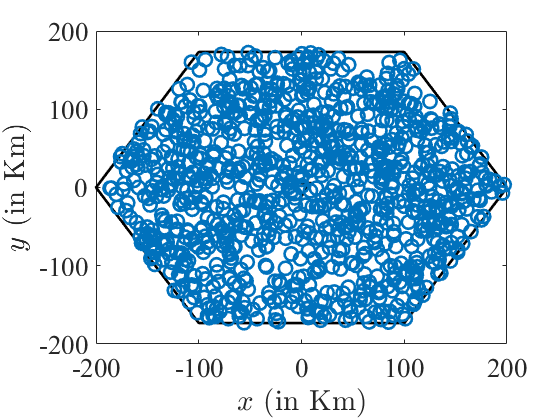

[G,~,user_pos] = massiveMIMOChannel(commcell,channel_type);

figure;

plot(x_cell,y_cell,'k','linewidth',linewidth);
hold on;
plot(0,0,'vk','linewidth',linewidth,'markersize',markersize);
plot(user_pos(:,1), user_pos(:,2),'o','color',color(1,:),'linewidth',linewidth,'markersize',markersize);

xlabel('$x$ (in Km)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
ylabel('$y$ (in Km)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');

set(gca,'fontname',fontname,'fontsize',fontsize);
xlim([-R R]);
ylim([-R R]);

% psi = ici(G);

% No Selection

[Q,W] = decoderMatrix(G,'mf');

settings.linkType = 'uplink';

thrgput_u = throughput(G,Q,pow_upl,settings);

sum_thrgput_u = N_schedule*sum(thrgput_u);
avg_thrgput_u = N_schedule*mean(thrgput_u);

settings.linkType = 'downlink';

thrgput_d = throughput(G,W,pow_dow,settings);

sum_thrgput_d = N_schedule*sum(thrgput_d);
avg_thrgput_d = N_schedule*mean(thrgput_d);

settings.coherenceTime           = (tau_c - tau_p)/N_schedule;                              % Coherence time in samples
settings.PilotTime               = 0;                              % Pilot time in samples

for alg_idx = 1:N_ALG
    H = G;
    
    for n = 1:N_schedule
        if size(H,2) >= L
            [user_sel_aux,H_sel,user_drop_aux,H_drop] = userSelector(H,algorithm_type{alg_idx},'fixed',L,[]);
            
            pow_upl_sel = ones(L,1);
            pow_dow_sel = ones(L,1)/L;
        else
            H_sel = H;
            
            user_sel_aux  = 1:rem(K,L);
            user_drop_aux = [];
            
            pow_upl_sel = ones(size(H,2),1);
            pow_dow_sel = ones(size(H,2),1)/size(H,2);                
        end
        
        if n > 1
            user_sel{n,alg_idx}  = user_drop{n-1,alg_idx}(user_sel_aux);
            user_drop{n,alg_idx} = user_drop{n-1,alg_idx}(user_drop_aux);
        else
            user_sel{n,alg_idx}  = user_sel_aux;
            user_drop{n,alg_idx} = user_drop_aux;
        end
        
        % psi_sel(:,alg_idx) = ici(H_sel);
        
        [Q,W] = decoderMatrix(H_sel,'mf');
        
        settings.linkType = 'uplink';
        
        thrgput_u_sel{n,alg_idx} = throughput(H_sel,Q,pow_upl_sel,settings);
        
        sum_thrgput_u_sel(n,alg_idx) = sum(thrgput_u_sel{n,alg_idx});
        avg_thrgput_u_sel(n,alg_idx) = mean(thrgput_u_sel{n,alg_idx});
        
        settings.linkType = 'downlink';
        
        thrgput_d_sel{n,alg_idx} = throughput(H_sel,W,pow_dow_sel,settings);
        
        sum_thrgput_d_sel(n,alg_idx) = sum(thrgput_d_sel{n,alg_idx});
        avg_thrgput_d_sel(n,alg_idx) = mean(thrgput_d_sel{n,alg_idx});
        
        H = H_drop;
    end
end

% figure;
% 
% for alg_idx = 1:length(legend_algo_2)
%     subplot(2,2,alg_idx);
%     
%     plot(x_cell,y_cell,'k','linewidth',linewidth);
%     hold on;
%     plot(0,0,'vk','linewidth',linewidth,'markersize',markersize);
%     for n = 1:N_schedule
%         plot(user_pos(user_sel{n,1},1), user_pos(user_sel{n,1},2),'o','color',color(n,:),'linewidth',linewidth,'markersize',markersize);
%     end
%     hold off;
%     
%     xlabel('$x$ (in Km)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
%     ylabel('$y$ (in Km)','fontname',fontname,'fontsize',fontsize,'interpreter','latex');
%     
%     title(legend_algo_2{alg_idx},'fontname',fontname,'fontsize',fontsize,'interpreter','latex');
%     
%     set(gca,'fontname',fontname,'fontsize',fontsize);
%     
%     xlim([-R R]);
%     ylim([-R R]);
% end

% figure;
% 
% for n = 1:N_schedule
%     subplot(7,8,n);
%     
%     bar(cat_2,1e-9*[sum_thrgput_u_sel(n,:)' sum_thrgput_d_sel(n,:)']);
%     
%     xlabel('Algorithms','fontname',fontname,'fontsize',fontsize);
%     ylabel('Sum-throughput (Gbps)','fontname',fontname,'fontsize',fontsize);
%     
%     title(['Time Slot' num2str(n)],'fontname',fontname,'fontsize',fontsize);
%     
%     %legend(legend_link,'fontname',fontname,'fontsize',fontsize);
%     
%     set(gca,'fontname',fontname,'fontsize',fontsize);    
% end

% figure;
% 
% for n = 1:N_schedule
%     subplot(7,8,n);
%     
%     bar(cat_2,1e-6*[avg_thrgput_u_sel(n,:)' avg_thrgput_d_sel(n,:)']);
%     
%     xlabel('Algorithms','fontname',fontname,'fontsize',fontsize);
%     ylabel('Average throughput (Mbps)','fontname',fontname,'fontsize',fontsize);
%     
%     title(['Time Slot' num2str(n)],'fontname',fontname,'fontsize',fontsize);
%     
%     %legend(legend_link,'fontname',fontname,'fontsize',fontsize);
%     
%     set(gca,'fontname',fontname,'fontsize',fontsize);    
% end

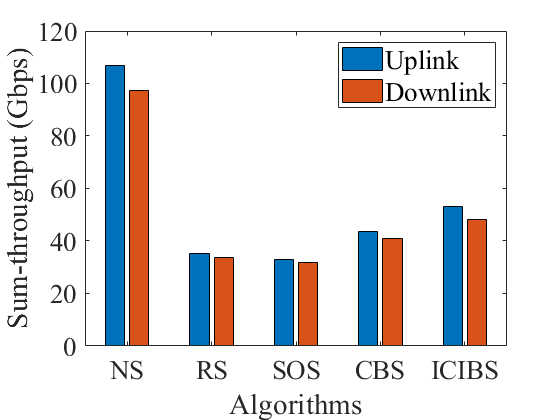

figure;

bar(cat_1,1e-9*[sum_thrgput_u sum_thrgput_d; sum(sum_thrgput_u_sel,1)' sum(sum_thrgput_d_sel,1)']);

xlabel('Algorithms','fontname',fontname,'fontsize',fontsize);
ylabel('Sum-throughput (Gbps)','fontname',fontname,'fontsize',fontsize);

legend(legend_link,'fontname',fontname,'fontsize',fontsize);

set(gca,'fontname',fontname,'fontsize',fontsize);

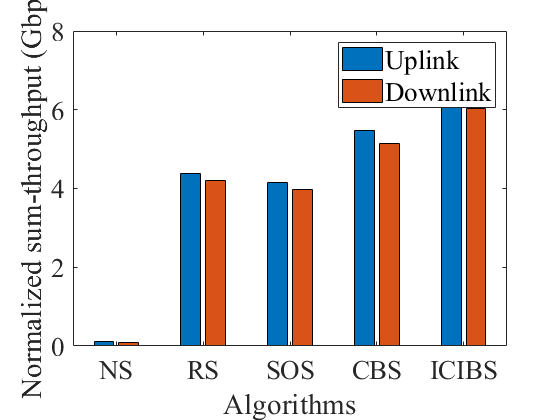

figure;

bar(cat_1,1e-9*[avg_thrgput_u avg_thrgput_d; sum(avg_thrgput_u_sel,1)' sum(avg_thrgput_d_sel,1)']);

xlabel('Algorithms','fontname',fontname,'fontsize',fontsize);
ylabel('Normalized sum-throughput (Gbps)','fontname',fontname,'fontsize',fontsize);

legend(legend_link,'fontname',fontname,'fontsize',fontsize);

set(gca,'fontname',fontname,'fontsize',fontsize);